# mutual information compare

compare the mutual information results with smoothed spike trains and non-smoothed spike trains

close all;clear;clc;
load("rat010_0615_9M1_5mPFC.mat")

M1spike = M1spike(:,3);

% check results
MI1 = mutualInformation(M1spike, mPFCspike);
for i=1:13
  MI2(i) = MIcontinuous(M1spike, mPFCspike(:,i));
  MI3(i) = MIcontinuous(gaussianSmooth(M1spike, 2), gaussianSmooth(mPFCspike(:,i),2));
end
MI1 == MI2

ans = 1×13 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1


% test difference
[~,index1]=sort(MI1, 'descend')

index1 =      7     8     5     6    13     1    12    10     3     9    11     2     4


[~,index1]=sort(MI2, 'descend')

index1 =      7     8     5     6    13     1    12    10     3     9    11     2     4


[~,index3]=sort(MI3, 'descend')

index3 =      7     5     8     6     1    13    12     3    11     9    10     2     4


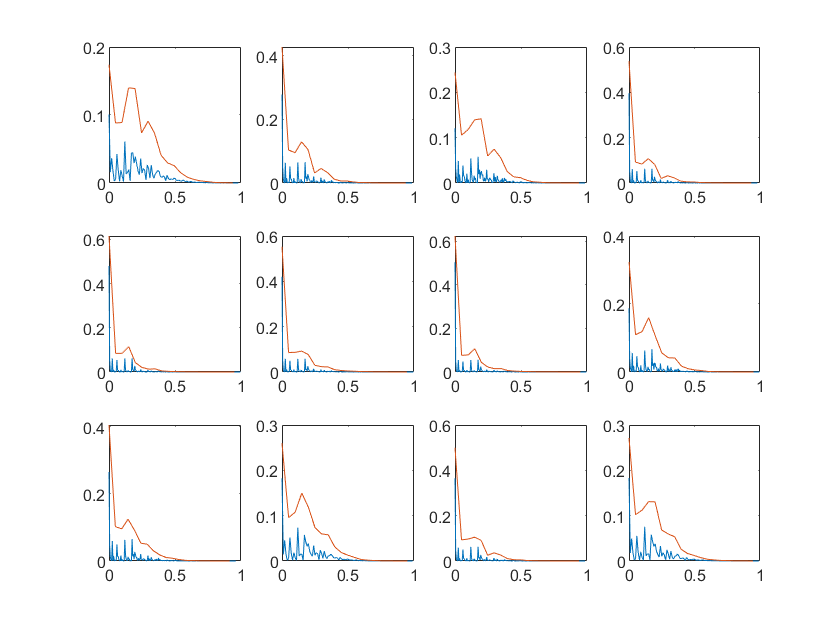

figure
for i=2:13
    subplot(3,4,i-1)
    [N,edges]=histcounts(gaussianSmooth(mPFCspike(:,i), 2));
    len = length(edges);
%     plot(edges(1:(len-1)), N/length(mPFCspike)/(edges(len)-edges(1))*(len-1))
    plot(edges(1:(len-1)), N/sum(N))
    hold on
%     [f,xi] = ksdensity(gaussianSmooth(mPFCspike(:,i), 2), linspace(min(gaussianSmooth(mPFCspike(:,i), 2)), max(gaussianSmooth(mPFCspike(:,i), 2)), 21));
%     plot(xi,f)
    [N,edges]  = histcounts(gaussianSmooth(mPFCspike(:,i), 2), linspace(min(gaussianSmooth(mPFCspike(:,i), 2)), max(gaussianSmooth(mPFCspike(:,i), 2)), 21), 'Normalization', 'probability');
    plot(edges(1:20), N)
    hold off
end